# Music Feature Lab experimental report

ELEC5305 Acoustics, Speech and Signal Processing Zihang Wang | SID 560746563 | 3 November 2026 Run all sections to regenerate the measurements and figures below. The accompanying project report provides the literature, methods and discussion.

## Objective

Investigate whether a defined brightness control produces repeatable acoustic changes, and whether the retained Dark, Neutral and Bright music recordings exhibit the intended three-level ordering. These are separate experiments: a fixed-source DSP calibration and a descriptive library study.

## Background

Spectral centroid is associated with timbre, but brightness is not fully described by one acoustic variable [1-3]. This project therefore displays several descriptors alongside an explicit signal-processing operation. Equal slider steps have not been established as equal perceptual steps. The application analyzes and processes existing recordings locally; it does not invoke a music-generation model. No listening study is reported here.

## Methodology and implementation

Stereo is retained for processing and export. Analysis uses the channel average, a symmetric 20 ms Hamming window, a nominal 4 ms hop and the next power-of-two FFT length. Centroid and bandwidth use amplitude weights, rather than MATLAB spectralCentroid's default power weights [4]. HF ratio is the sum of squared single-sided amplitudes at f >= 4000 Hz, divided by their full-band sum. Slope is a least-squares dB/Hz fit with a relative spectral floor. Near-silent frames are omitted from spectral means. RMS describes the complete mono signal. Positive spectral flux and the onset detector (50 ms minimum separation) are descriptive, not beat labels. Pitch is optional in the App but disabled in these measurements [5]. This script never clears the workspace or closes unrelated figures.

mflReportDir = fileparts(mfilename('fullpath'));
% Headless Live Editor evaluation may not expose mfilename; resolve the
% opened script on the path as a fallback, without any computer-specific path.
if ~isfile(fullfile(fileparts(mflReportDir),'MusicFeatureLab','MusicAnalysis.m'))
    mflReportDir = fileparts(which('Experiment_Live.mlx'));
end
mflProjectDir = fileparts(mflReportDir);
mflAppDir = fullfile(mflProjectDir,'MusicFeatureLab');
assert(isfile(fullfile(mflAppDir,'MusicAnalysis.m')),'Keep the submission folders together.');
addpath(mflAppDir,fullfile(mflAppDir,'tests'));
mflResultsDir = fullfile(mflProjectDir,'results');
if ~isfolder(mflResultsDir), mkdir(mflResultsDir); end
[~,mflImplName,mflImplExt] = fileparts(which('MusicAnalysis'));
fprintf('Environment: MATLAB %s\nAnalysis module: %s%s\n',version,mflImplName,mflImplExt);

Environment: MATLAB 26.1.0.3312084 (R2026a) Update 4
Analysis module: MusicAnalysis.m


## Code and results 1 Original recording

The calibration recording is demo.wav, a copy of the original test.wav. Its source and sampling rate differ from the retained music library.

[mflAudio,mflFs] = audioread(fullfile(mflAppDir,'demo.wav'));
mflOriginal = MusicAnalysis.analyze(mflAudio,mflFs,false);
mflSourceInfo = MusicAnalysis.featureTable(mflOriginal,"Calibration source");
disp(mflSourceInfo(:,{'Duration_s','SampleRate_Hz','Channels','Centroid_Hz','HFRatio','RMS'}));

    Duration_s    SampleRate_Hz    Channels    Centroid_Hz     HFRatio       RMS  
    __________    _____________    ________    ___________    _________    _______

      91.951          44100           2          729.23       0.0039435    0.20369



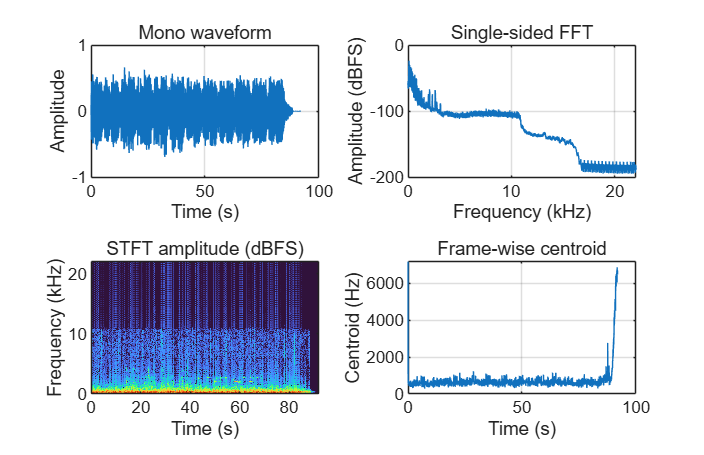

figure('Name','Calibration source analysis','Color','w','Position',[120 100 960 620]);
tiledlayout(2,2,'TileSpacing','compact');
nexttile; plot(mflOriginal.tWave,mflOriginal.xWave); grid on;
xlabel('Time (s)'); ylabel('Amplitude'); title('Mono waveform');
nexttile; plot(mflOriginal.fSpectrum/1000,mflOriginal.spectrumDB); grid on;
xlabel('Frequency (kHz)'); ylabel('Amplitude (dBFS)'); title('Single-sided FFT');
nexttile; imagesc(mflOriginal.tFrames,mflOriginal.fSTFT/1000,mflOriginal.stftDB);
axis xy; ylim([0 mflFs/2000]); xlabel('Time (s)'); ylabel('Frequency (kHz)');
title('STFT amplitude (dBFS)'); colormap turbo;
clim(max(mflOriginal.stftDB(:))+[-80 0]);
nexttile; plot(mflOriginal.tFrames,mflOriginal.centroidSeries); grid on;
xlabel('Time (s)'); ylabel('Centroid (Hz)'); title('Frame-wise centroid');

## Code and results 2 Symmetric brightness processing

For FFT bin k, q(k) = 2*min(k,N-k)/N and gain = 10^(6*b*q(k)/20). Gain in dB varies linearly with folded frequency, with nominal Nyquist gain from -6 to +6 dB. Matching gains at positive/negative frequencies preserve a real signal. Only peaks above 1 cause a uniform scaling. Measurements are recomputed from the actual output after that scaling.

[mflIdentity,mflGainInfo] = MusicAnalysis.brightness(mflAudio,mflFs,0);
assert(isequal(mflIdentity,mflAudio),'Zero brightness must preserve this source.');
disp(mflGainInfo);

        gainDB: 0
     peakScale: 1
     inputPeak: 0.7821
    outputPeak: 0.7821



mflCalibration = MusicAnalysis.calibration(mflAudio,mflFs,-1:.25:1);
disp(mflCalibration(:,{'Brightness','Centroid_Hz','HFRatio','Slope_dB_Hz','RMS'}));

    Brightness    Centroid_Hz     HFRatio     Slope_dB_Hz      RMS  
    __________    ___________    _________    ___________    _______

         -1         692.73       0.0027493    -0.0014943     0.20262
      -0.75          701.1       0.0030135    -0.0015006     0.20289
       -0.5         709.96       0.0033001    -0.0015071     0.20315
      -0.25         719.33       0.0036099    -0.0015137     0.20342
          0         729.23       0.0039435    -0.0015206     0.20369
       0.25          739.7       0.0043016    -0.0015277     0.20395
        0.5         750.75       0.0046844    -0.0015349     0.20422
       0.75         762.42       0.0050919    -0.0015422     0.20449
          1         774.73       0.0055241    -0.0015498     0.20476



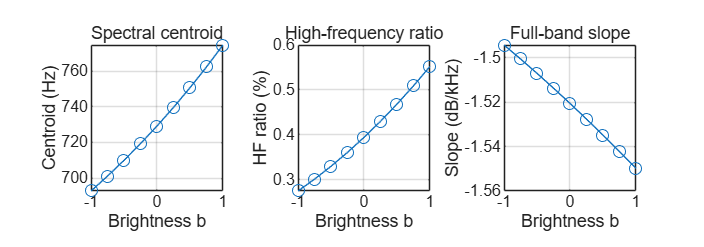

figure('Name','Nine-level brightness calibration','Color','w','Position',[120 100 1050 370]);
tiledlayout(1,3,'TileSpacing','compact');
nexttile; plot(mflCalibration.Brightness,mflCalibration.Centroid_Hz,'-o'); grid on;
xlabel('Brightness b'); ylabel('Centroid (Hz)'); title('Spectral centroid');
nexttile; plot(mflCalibration.Brightness,100*mflCalibration.HFRatio,'-o'); grid on;
xlabel('Brightness b'); ylabel('HF ratio (%)'); title('High-frequency ratio');
nexttile; plot(mflCalibration.Brightness,1000*mflCalibration.Slope_dB_Hz,'-o'); grid on;
xlabel('Brightness b'); ylabel('Slope (dB/kHz)'); title('Full-band slope');

fprintf('Centroid: %.2f -> %.2f -> %.2f Hz for b=-1,0,+1\n',mflCalibration.Centroid_Hz([1 5 9]));

Centroid: 692.73 -> 729.23 -> 774.73 Hz for b=-1,0,+1


fprintf('HF ratio: %.4f -> %.4f -> %.4f %%\n',100*mflCalibration.HFRatio([1 5 9]));

HF ratio: 0.2749 -> 0.3944 -> 0.5524 %


assert(all(diff(mflCalibration.Centroid_Hz)>0) && all(diff(mflCalibration.HFRatio)>0));
writetable(mflCalibration,fullfile(mflResultsDir,'calibration.csv'));

## Code and results 3 Recompute all 15 retained recordings

Five files per label share the filename seeds 12315 to 12355. Every file is analyzed at its own sample rate. No stored feature values are used as input to the analysis. Reference CSVs are used only in the checks below.

mflConditions = ["Dark","Neutral","Bright"];
mflSeeds = [12315;12325;12335;12345;12355];
mflRows = cell(15,1); mflCount = 0;
for mflC = 1:3
    for mflS = 1:5
        mflName = sprintf('%s_%d.wav',lower(mflConditions(mflC)),mflSeeds(mflS));
        [mflClip,mflRate] = audioread(fullfile(mflAppDir,'data','music library',mflConditions(mflC),mflName));
        mflMeasured = MusicAnalysis.analyze(mflClip,mflRate,false);
        mflRow = MusicAnalysis.featureTable(mflMeasured,fullfile(mflConditions(mflC),mflName));
        mflRow.Condition = mflConditions(mflC); mflRow.Seed = mflSeeds(mflS);
        mflCount = mflCount+1; mflRows{mflCount} = mflRow;
    end
end
mflLibrary = vertcat(mflRows{:});
assert(height(mflLibrary)==15 && all(isfinite(mflLibrary.Centroid_Hz)));
disp(mflLibrary(:,{'Condition','Seed','Centroid_Hz','HFRatio','RMS'}));

    Condition    Seed     Centroid_Hz     HFRatio       RMS  
    _________    _____    ___________    _________    _______

    "Dark"       12315       971.1       0.0041711    0.26952
    "Dark"       12325      2395.4        0.030233    0.13777
    "Dark"       12335      3895.6        0.089889    0.13832
    "Dark"       12345      2431.1        0.025174    0.21735
    "Dark"       12355      2917.4        0.020711    0.16208
    "Neutral"    12315      971.62        0.002576    0.22377
    "Neutral"    12325      2457.9         0.02784    0.17517
    "Neutral"    12335      4408.9         0.10523    0.12117
    "Neutral"    12345      2523.9        0.022978    0.18881
    "Neutral"    12355      3705.8        0.043457    0.12258
    "Bright"     12315      1052.7       0.0051504    0.19521
    "Bright"     12325      2306.7        0.027498    0.17611
    "Bright"     12335      3849.7        0.068582    0.10755
    "Bright"     12345      2504.7        0.023916    0.16526
    "Br

writetable(mflLibrary,fullfile(mflResultsDir,'library_features.csv'));

## Code and results 4 Condition summaries and filename seed pairing

The file is the observation. SD uses the sample (n-1) convention. Filename pairing describes the retained data; it does not prove controlled generation.

mflCvalues = zeros(5,3); mflHvalues = zeros(5,3);
for mflC = 1:3
    mflSubset = sortrows(mflLibrary(mflLibrary.Condition==mflConditions(mflC),:),'Seed');
    mflCvalues(:,mflC) = mflSubset.Centroid_Hz;
    mflHvalues(:,mflC) = 100*mflSubset.HFRatio;
end
mflSummary = table(mflConditions',mean(mflCvalues,1)',std(mflCvalues,0,1)', ...
    mean(mflHvalues,1)',std(mflHvalues,0,1)', ...
    'VariableNames',{'Condition','Cmean_Hz','Csd_Hz','HFmean_pct','HFsd_pct'});
disp(mflSummary);

    Condition    Cmean_Hz    Csd_Hz    HFmean_pct    HFsd_pct
    _________    ________    ______    __________    ________

    "Dark"        2522.1     1057.4      3.4036       3.2718 
    "Neutral"     2813.6     1317.6      4.0416       3.9065 
    "Bright"        2537     1020.9      2.9576       2.3458 



mflPairs = table(mflSeeds,mflCvalues(:,1),mflCvalues(:,2),mflCvalues(:,3), ...
    mflCvalues(:,3)-mflCvalues(:,1),mflHvalues(:,3)-mflHvalues(:,1), ...
    'VariableNames',{'Seed','C_Dark','C_Neutral','C_Bright','BminusD_Hz','BminusD_HFpct'});
disp(mflPairs);

    Seed     C_Dark    C_Neutral    C_Bright    BminusD_Hz    BminusD_HFpct
    _____    ______    _________    ________    __________    _____________

    12315     971.1     971.62       1052.7       81.594        0.097932   
    12325    2395.4     2457.9       2306.7       -88.72        -0.27357   
    12335    3895.6     4408.9       3849.7      -45.934         -2.1307   
    12345    2431.1     2523.9       2504.7       73.655        -0.12577   
    12355    2917.4     3705.8       2971.3       53.889          0.2024   



mflCentroidOrdered = sum(all(diff(mflCvalues,1,2)>0,2));
mflHFOrdered = sum(all(diff(mflHvalues,1,2)>0,2));
fprintf('Strict Dark < Neutral < Bright: centroid %d/5; HF ratio %d/5\n',mflCentroidOrdered,mflHFOrdered);

Strict Dark < Neutral < Bright: centroid 1/5; HF ratio 0/5


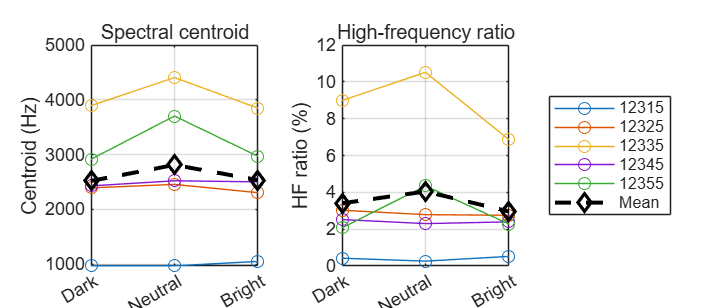

figure('Name','Features by filename seed','Color','w','Position',[120 100 960 420]);
tiledlayout(1,2,'TileSpacing','compact');
nexttile; plot(1:3,mflCvalues','-o'); hold on;
plot(1:3,mean(mflCvalues,1),'k--d','LineWidth',2); hold off; grid on;
xticks(1:3); xticklabels(mflConditions); ylabel('Centroid (Hz)'); title('Spectral centroid');
nexttile; plot(1:3,mflHvalues','-o'); hold on;
plot(1:3,mean(mflHvalues,1),'k--d','LineWidth',2); hold off; grid on;
xticks(1:3); xticklabels(mflConditions); ylabel('HF ratio (%)'); title('High-frequency ratio');
legend([string(mflSeeds);"Mean"],'Location','eastoutside');

writetable(mflSummary,fullfile(mflResultsDir,'condition_summary.csv'));
writetable(mflPairs,fullfile(mflResultsDir,'paired_seed_contrasts.csv'));

## Code and results 5 Verify consistency with the written report

These are tolerance checks against the report's retained measurements. They reveal analysis drift instead of substituting reference values for data.

mflRefCal = readtable(fullfile(mflReportDir,'data','calibration.csv'));
mflRefLib = readtable(fullfile(mflReportDir,'data','recomputed_library_features.csv'),'TextType','string');
mflSorted = sortrows(mflLibrary,{'Condition','Seed'});
mflRefLib = sortrows(mflRefLib,{'Condition','Seed'});
mflCalibrationError = max(abs(mflCalibration.Centroid_Hz-mflRefCal.Centroid_Hz));
mflLibraryError = max(abs(mflSorted.Centroid_Hz-mflRefLib.Centroid_Hz));
assert(mflCalibrationError<1e-6 && mflLibraryError<1e-6,'The report and recomputation disagree.');
assert(max(abs(mflSorted.HFRatio-mflRefLib.HFRatio))<1e-12);
fprintf('Maximum centroid differences from report: calibration %.3g Hz, library %.3g Hz\n', ...
    mflCalibrationError,mflLibraryError);

Maximum centroid differences from report: calibration 4.55e-13 Hz, library 4.55e-12 Hz


## Code and results 6 FM synthesis and numerical verification

This is a reproducible demonstration of the App's synthesis module. It is not an additional generated-music condition or a listening evaluation.

mflFM = MusicAnalysis.synthesize(440,110,2,2,44100);
mflFMresult = MusicAnalysis.analyze(mflFM,44100,false);
mflFMinfo = MusicAnalysis.featureTable(mflFMresult,"FM demonstration");
disp(mflFMinfo(:,{'Duration_s','SampleRate_Hz','Centroid_Hz','HFRatio','RMS'}));

    Duration_s    SampleRate_Hz    Centroid_Hz     HFRatio        RMS  
    __________    _____________    ___________    __________    _______

        2             44100          679.07       2.0151e-05    0.12819



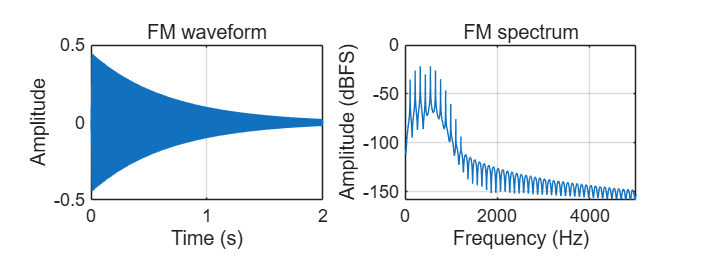

figure('Name','FM synthesis demonstration','Color','w','Position',[120 100 900 340]);
tiledlayout(1,2,'TileSpacing','compact');
nexttile; plot(mflFMresult.tWave,mflFMresult.xWave); grid on;
xlabel('Time (s)'); ylabel('Amplitude'); title('FM waveform');
nexttile; plot(mflFMresult.fSpectrum,mflFMresult.spectrumDB); grid on; xlim([0 5000]);
xlabel('Frequency (Hz)'); ylabel('Amplitude (dBFS)'); title('FM spectrum');

mflTests = run_music_analysis_tests;

               Test                Passed    Message 
    ___________________________    ______    ________

    "testIdentityAndSymmetry"      true      "Passed"
    "testNormalizedOutput"         true      "Passed"
    "testToneAnalysis"             true      "Passed"
    "testSilenceAndShortInput"     true      "Passed"
    "testCalibration"              true      "Passed"
    "testDisplayDecimation"        true      "Passed"
    "testOptionalPitchTimebase"    true      "Passed"
    "testSynthesis"                true      "Passed"



assert(all(mflTests.Passed),'A numerical verification group failed.');
writetable(mflTests,fullfile(mflResultsDir,'numerical_verification.csv'));

## Discussion

Centroid and HF ratio increase at every calibration step for the fixed source. The measured spectral slope becomes more negative, so it is not a reliable sole indicator of this control. The cause of that trend was not established. The applied FFT gain and an averaged STFT descriptor differ. The music library does not show a stable three-condition ordering: only 1/5 seed groups satisfy the centroid order and 0/5 satisfy the HF order. The calibration and library use different sources, durations and sample rates; their absolute features cannot prove superiority of DSP over AI. Only one Dark/12315 generation request is documented in the original Python script. The model/checkpoint and all generation histories remain unverified. Matching seeds alone do not establish causal prompt effects. No subjective brightness ratings, participant data or significance tests were obtained. Mono averaging can cancel out-of-phase channel information.

## Conclusion

The integrated App and this Live Script provide repeatable local analysis. The positive result is predictable centroid/HF change for one calibration recording. The negative result is the absence of consistent label ordering in the retained music library. More source recordings, complete generation manifests and controlled, level-matched listening tests are needed before perceptual or general model claims can be made.

mflCompletion = struct('Status','Passed','LibraryFiles',height(mflLibrary), ...
    'CalibrationLevels',height(mflCalibration),'NumericalGroupsPassed',sum(mflTests.Passed), ...
    'CentroidOrderedSeeds',mflCentroidOrdered,'HFOrderedSeeds',mflHFOrdered, ...
    'MATLABVersion',version,'RunAt',char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')));
mflFile = fopen(fullfile(mflResultsDir,'run_summary.json'),'w','n','UTF-8');
assert(mflFile>0,'Cannot write the run summary.');
fprintf(mflFile,'%s',jsonencode(mflCompletion,'PrettyPrint',true)); fclose(mflFile);
disp(mflCompletion);

                   Status: 'Passed'
             LibraryFiles: 15
        CalibrationLevels: 9
    NumericalGroupsPassed: 8
     CentroidOrderedSeeds: 1
           HFOrderedSeeds: 0
            MATLABVersion: '26.1.0.3312084 (R2026a) Update 4'
                    RunAt: '2026-11-03 05:41:38'



fprintf('All outputs were regenerated successfully.\n');

All outputs were regenerated successfully.


## References

[1] Caclin et al., JASA 118(1), 471-482, 2005. doi:10.1121/1.1929229. [2] Kazazis et al., JASA 149(6), 3785-3796, 2021. doi:10.1121/10.0005058. [3] Kazazis et al., Frontiers in Psychology 13, 835401, 2022. doi:10.3389/fpsyg.2022.835401. [4] MathWorks, spectralCentroid documentation, accessed 3 November 2026. [https://www.mathworks.com/help/audio/ref/spectralcentroid.html](https://www.mathworks.com/help/audio/ref/spectralcentroid.html) [5] MathWorks, pitch documentation, accessed 3 November 2026. [https://www.mathworks.com/help/audio/ref/pitch.html](https://www.mathworks.com/help/audio/ref/pitch.html)

## AI assistance statement

I selected the topic, ran the original audio generation, and wrote the original MATLAB code with AI guidance. I used AI assistance to plan the experiments, summarize and analyze the results, organize materials and references, improve language and grammar, and draft and revise the report. OpenAI Codex also helped develop, integrate and review the revised MATLAB App and code and verify results. Numerical results were computed from the retained audio using the supplied code. No missing generation records, participant responses or subjective ratings were invented.